adc = readmatrix('adc.csv')

adc =      1
     2
     0
     5
     0
     0
    10
     8
     2
     0


theory = readmatrix('theory.csv')

theory =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


settings = readmatrix('settings.csv')

settings =    13.0000  100.0000    3.3000    8.0000



Vref = settings(3)

Vref = 3.3000

SamplingFrequency = settings(2)

SamplingFrequency = 100

TMeasure = settings(1)

TMeasure = 13

Nadc = settings(4)

Nadc = 8

v = adc/(2^Nadc) * Vref 

v =     0.0129
    0.0258
         0
    0.0645
         0
         0
    0.1289
    0.1031
    0.0258
         0


t = 0 : 1/SamplingFrequency : TMeasure-1/SamplingFrequency   

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


N = 10

N = 10

y = medfilt1(v, N)

y =          0
         0
         0
    0.0064
    0.0193
    0.0193
    0.0258
    0.0322
    0.0322
    0.0129


fig = figure();
hold all
plot(t,v, '.', 'DisplayName', 'АЦП')
plot(t,y, 'DisplayName', 'Медианный фильтр, N = 10')





z = meanfilt(v, N)

x =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0    0.0129         0    0.0387         0         0         0         0         0         0         0    0.0129         0         0         0         0    0.0129         0         0         0         0         0         0    0.0258         0


m =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

m =     0.0129         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0    0.0129         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0    0.0129         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0    0.0129         0         0         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0    0.0129         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0    0.0129         0    0.0387         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0    0.0129         0    0.0387         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0    0.0129         0    0.0387         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0    0.0129         0    0.0387         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0    0.0129         0    0.0387         0         0         0         0         0         0         0         0         0         0         0     

m =     0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0    0.0129         0    0.0387         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0    0.0129         0    0.0387         0         0         0         0         0         0         0         0         0         0         0     

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 1×1300
    0.0361    0.0412    0.0425    0.0425    0.0361    0.0361    0.0361    0.0296    0.0193    0.0168    0.0361    0.0412    0.0425    0.0425    0.0361    0.0361    0.0361    0.0296    0.0193    0.0168    0.0180    0.0116    0.0142    0.0142    0.0142    0.0142    0.0142    0.0090    0.0090    0.0129


z = 1×1300
    0.0361    0.0412    0.0425    0.0425    0.0361    0.0361    0.0361    0.0296    0.0193    0.0168    0.0361    0.0412    0.0425    0.0425    0.0361    0.0361    0.0361    0.0296    0.0193    0.0168    0.0180    0.0116    0.0142    0.0142    0.0142    0.0142    0.0142    0.0090    0.0090    0.0129


m = meanfilt(v, N)

x = 1×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645         0         0         0         0    0.0129         0    0.0387         0


m = 10×1300
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

m = 10×1300
    0.0129         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0         0         0         0         0         0     

m = 10×1300
    0.0129         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0         0         0         0         0         0     

m = 10×1300
    0.0129    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0         0         0         0         0         0     

m = 10×1300
    0.0129    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0         0         0         0         0         0     

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289         0         0         0         0     

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031         0         0         0     

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0         0     

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0         0     

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645     

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031         0         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0         0         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645         0         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0         0         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0         0
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0         0
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

m = 10×1300
    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0129    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129
    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0258         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0
         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0.0387         0         0         0         0    0.0645         0         0    0.0129         0    0.0645
    0.0645         0         0    0.1289    0.1031    0.0258         0    0.0645    0

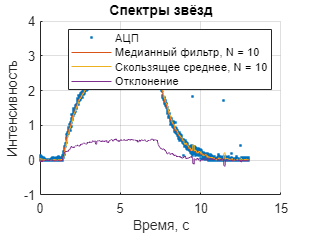

z = z'
plot(t,z, 'DisplayName', 'Скользящее среднее, N = 10')

legend()

xlabel('Время, c')
ylabel('Интенсивность')
grid on
title('Спектры звёзд')
delta = theory -z 
plot(t, delta, 'DisplayName', 'Отклонение')